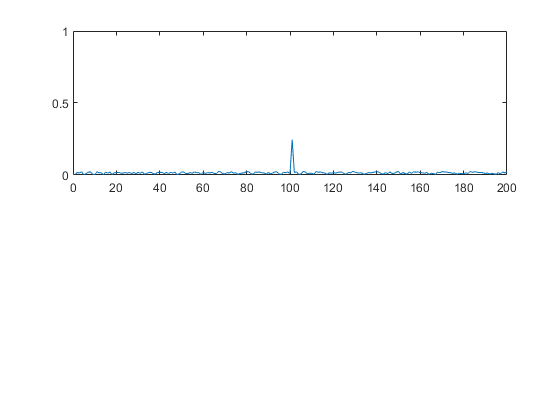

clc;

%% Radar Specifications 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Frequency of operation = 77GHz
% Max Range = 200m
% Range Resolution = 1 m
% Max Velocity = 100 m/s
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

operationFrequency = 77;
maxRange = 200;
resolutionRange = 1;
maxVelocity = 100;

LIGHT_SPEED = 3e8;
 
%User Defined Range and Sequence Velocity of target
%{
 Define the target's initial position and velocity. Note: Velocity
 remains contant
%} 

targetPosition = 100;
targetVelocity = 10; % m/s
 


% FMCW Waveform Generation
%{
  Design the FMCW waveform by giving the specs of each of its parameters.
  Calculate the Bandwidth (B), Chirp Time (Tchirp) and Slope (slope) of the FMCW
  chirp using the requirements above.
%}
sweepBW = LIGHT_SPEED / (2 * resolutionRange);
sweepTF = 5.5;
Tchirp  = sweepTF * (2 * maxRange / LIGHT_SPEED);
slope   = sweepBW / Tchirp;


% Operating carrier frequency of Radar 
carrierFrequency = 77e9; 

%{                                                          
The number of chirps in one sequence. Its ideal to have 2^ value for the ease of 
running the FFT for Doppler Estimation. 
%}
nCells = 64; % #of doppler cells OR #of sent periods % number of chirps

% The number of samples on each chirp. 
nRange = 512; %for length of time OR # of range cells

% Timestamp for running the displacement scenario for every sample on each chirp
t = linspace(0, nCells * Tchirp, nRange * nCells); %total time for samples


%Creating the vectors for Tx, Rx and Mix based on the total samples input.
Tx  = zeros(1, length(t)); %transmitted signal
Rx  = zeros(1, length(t)); %received signal
Mix = zeros(1, length(t)); %beat signal

% Similar vectors for range_covered and time delay.
r_t = zeros(1, length(t));
td  = zeros(1, length(t));


%% Signal generation and Moving Target simulation

% Running the radar scenario over the time. 
for i=1:length(t)         
    
    % For each time stamp update the Range of the Target for constant velocity. 
    r_t(i) = (targetVelocity * t(i)) + targetPosition;
    td(i)  = (2 * r_t(i)) / LIGHT_SPEED;
  
    % For each time sample we need update the transmitted and received signal. 
    Tx(i) = cos(2 * pi * (carrierFrequency * t(i) + (slope * t(i) ^ 2) / 2.0));
    Rx(i) = cos(2 * pi * (carrierFrequency * (t(i) - td(i)) + (slope * (t(i) - td(i)) ^ 2) / 2.0));

    
    %{
    Now by mixing the Transmit and Receive generate the beat signal
    This is done by element wise matrix multiplication of Transmit anCells
    %}
    
    %Receiver Signal
    Mix(i) = Tx(i).*Rx(i);
    
end

%% RANGE MEASUREMENT

%{
Reshape the vector into Nr*Nd array. Nr and Nd here would also define the 
size of Range and Doppler FFT respectively.
%}
Mix = reshape(Mix, [nRange, nCells]);

%Run the FFT on the beat signal along the range bins dimension (Nr) and normalize.
signalFFT = fft(Mix, nRange);
signalFFT = signalFFT / nRange;


% Take the absolute value of FFT output
signalFFT = abs(signalFFT);

%{
Output of FFT is double sided signal, but we are interested in only one side 
of the spectrum. Hence we throw out half of the samples.
%}
signalFFT = signalFFT(1:nRange / 2);

% Plotting the range
figure ('Name','Range from First FFT')
subplot(2,1,1)

% Plot FFT output 
plot(signalFFT);
 
axis ([0 200 0 1]); %[range, resolution]

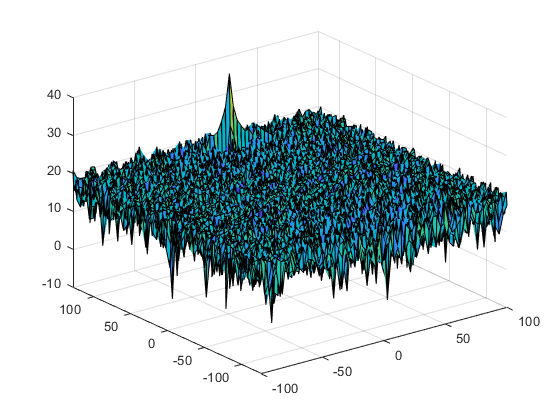




%% RANGE DOPPLER RESPONSE
%{
The 2D FFT implementation is already provided here. This will run a 2DFFT
on the mixed signal (beat signal) output and generate a range doppler
map. You will implement CFAR on the generated RDM.

%Range Doppler Map Generation.
The output of the 2D FFT is an image that has reponse in the range anCells
doppler FFT bins. So, it is important to convert the axis from bin sizes
to range and doppler based on their Max values.
%}
Mix = reshape(Mix, [nRange, nCells]);

% 2D FFT using the FFT size for both dimensions.
signalFFT2 = fft2(Mix, nRange, nCells);
 
% Taking just one side of signal from Range dimension.
signalFFT2 = signalFFT2(1:nRange / 2, 1:nCells);
signalFFT2 = fftshift (signalFFT2);
RDM = abs(signalFFT2);
RDM = 10 * log10(RDM) ;

%{
Use the surf function to plot the output of 2DFFT anCells to show axis in 
both dimensions
%}
doppler_axis = linspace(-100, 100, nCells);
range_axis = linspace(-200, 200, nRange / 2) * ((nRange / 2) / 400);
figure('Name', '2DFFT'), surf(doppler_axis, range_axis, RDM);

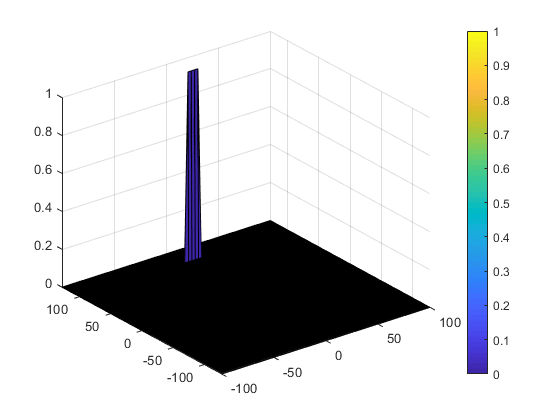


%% CFAR implementation

% Slide Window through the complete Range Doppler Map

% Select the number of Training Cells in both the dimensions.

trainingRange = 10;
trainingDoppler = 8;
%{
Select the number of Guard Cells in both dimensions around the Cell under 
test (CUT) for accurate estimation
%}
guardRange = 4;
guardDoppler = 4;

% Offset the threshold by SNR value in dB
offset = 10;

% Create a vector to store noise_level for each iteration on training cells
noise_level = zeros(1,1);

%{
Design a loop such that it slides the CUT across range doppler map by
giving margins at the edges for Training and Guard Cells.
For every iteration sum the signal level within all the training
cells. To sum convert the value from logarithmic to linear using db2pow
function. Average the summed values for all of the training
cells used. After averaging convert it back to logarithimic using pow2db.
Further add the offset to it to determine the threshold. Next, compare the
signal under CUT with this threshold. If the CUT level > threshold assign
it a value of 1, else equate it to 0.
%}

[rows_RDM, cols_RDM] = size(RDM);

% Use RDM[x,y] as the matrix from the output of 2D FFT for implementing CFAR
RDM_pow = db2pow(RDM);

for i = trainingRange + guardRange + 1:(nRange/2) - (trainingRange + guardRange)
    for j = trainingDoppler + guardDoppler + 1:nCells - (trainingDoppler + guardDoppler)
        cumulative = zeros(1,1);
        for m = i - (trainingRange + guardRange):i + (trainingRange + guardRange)
            for n = j - (trainingDoppler + guardDoppler):j + (trainingDoppler + guardDoppler)
                 if((abs(i - m) > guardRange) || (abs(j - n) > guardDoppler))
                        cumulative = cumulative + RDM_pow(m, n);   
                 end
            end
        end
        avg = cumulative / ((2 * (trainingDoppler + guardDoppler + 1) * 2 * (trainingRange + guardRange + 1) - (guardRange * guardDoppler) - 1));
        threshold = pow2db(avg) + offset;
        CUT = RDM(i, j);
        if(CUT > threshold)
            RDM(i, j) = 1;
        else
            RDM(i, j) = 0;
        end
    end
end


%{
The process above will generate a thresholded block, which is smaller 
than the Range Doppler Map as the CUT cannot be located at the edges of
matrix. Hence,few cells will not be thresholded. To keep the map size same
set those values to 0. 
%}

for i = 1: trainingRange + guardRange
    RDM(i, :) = 0;
    RDM(nRange / 2 - i - 1:nRange / 2, :) = 0;
end
for i = 1:trainingDoppler + guardDoppler
    RDM(:, i) = 0;
    RDM(:, nCells - i - 1:nCells) = 0;
end

%{
Display the CFAR output using the Surf function like we did for Range 
Doppler Response output.
%}
figure('Name','CA-CFAR Filtered RDM'), surf(doppler_axis, range_axis, RDM);
colorbar;